T=readtable('C:\Users\Corentin\OneDrive\Bureau\ECL 1\S5\MTH\Statistiques\vols.txt','Delimiter','\t',ReadVariableNames=true)

T = 670×1 table
     vols 
    ______

    1.9098
    1.9047
    1.9154
    1.9228
    1.9051
    1.9498
    1.9166
    1.9149
    1.9031
    1.9149
    1.9023
    1.9253
    1.9381
    1.9316
    1.9045
     1.904


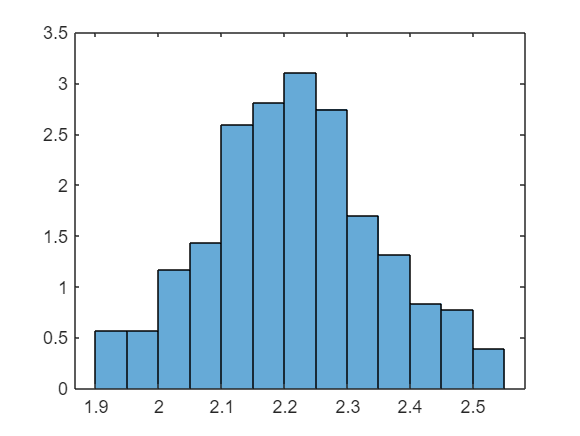

histogram(T.vols,'Normalization','pdf')

moy=mean(T.vols)

moy = 2.2164

Var=var(T.vols)

Var = 0.0190

J=13;
a=min(T.vols);
b=max(T.vols);
k=(b-a)/J;
L=zeros(J,1);
s_hist=0;
for i=0:J-1
    c=0;
    for j=1:length(T.vols)
        if  and(a+i*k<T.vols(j),T.vols(j)<a+(i+1)*k);
            c=c+1;
        end
    end
    L(i+1)=c;
    s_hist=s_hist+(a+i*k)*c;
end
moy_hist=s_hist/length(T.vols)

moy_hist = 2.1851